# Synchronization In-Class Exercises

## Hypothesis Testing for Poisson Random Variables

We will simulate hypothesis testing for discriminating between two Poisson distributions.  This type of detector occurs in optical systems where the receiver counts the number of photons.  The unknown variable is x=0 or 1.  We receive a discrete random variable `y` with conditional probability:

- `P(y|x=0)` is Poisson with rate `lam0`.  `P(x=0)=p0`

- `P(y|x=1)` is Poisson with rate `lam1`.  `P(x=1)=p1`

`The parameters are below`

lam0 = 10;  % Rate when x=0
lam1 = 20;  % Rate when x=1
p0 = 0.8;   % P(x=0)=1-P(x=1)
ntrial = 1000;  % Number of trials to test

Generate a vector `x` of length ntrial with elements `x(i) = 0` or `1` with the above probabilities. 

% TODO:  
%   x = ...
x = rand(ntrial,1) > p0;

Next, generate a vector `y` following  the Poisson distribution.  You can use the `poissrnd` function.

% TODO:
%   lam = ...
%   y = poissrnd(...);
lam = lam0*(x==0) + lam1*(x==1);
y = poissrnd(lam);

Plot a histogram of the values of `y` when `x=0` and `x=`1.  You can use the `histogram` command and use one subplot for each value of x

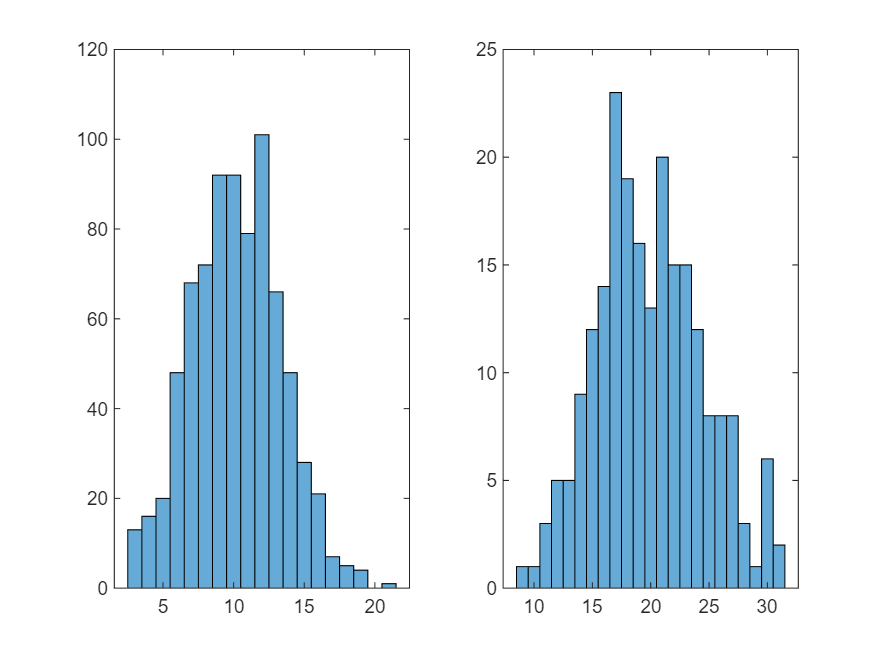

% TODO
xvals = [0,1];
nx = length(xvals);
for i = 1:nx
    I = (x==xvals(i));
    subplot(1,nx,i);
    histogram(y(I));
end

We will finally simulate a simple threshold detector:  For each value of `t` in `ttest`, consider the estimator:

`    xhat(i) = 1   if y(i) >= t`

`    xhat(i) = 0   if y(i) < t`

Simulate this detector and measure the False alarm probability `pfa` and the Missed detection probability `pmd`.  Plot both `pfa` and `pmd` vs. the threshold.

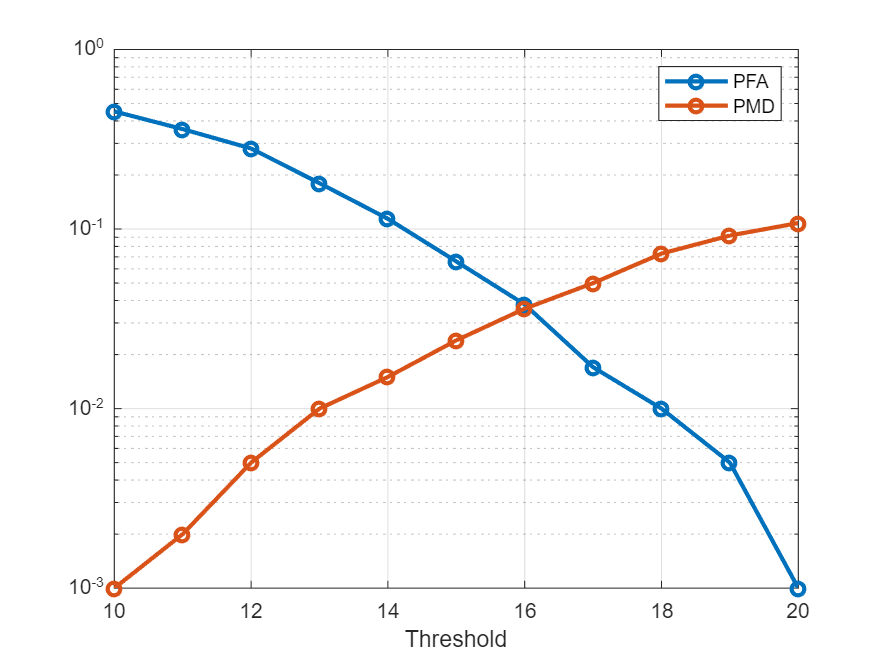


ttest = (lam0:lam1);  % Thresholds to test

nt = length(ttest);
pfa = zeros(nt,1);
pmd = zeros(nt,1);
for i = 1:nt

    t = ttest(i);

    % TODO: 
    %    xhat = ...
    %    pfa(i) = ...
    %    pmd(i) = ...
    xhat = (y >= t);
    pfa(i) = mean((xhat==1) & (x == 0));
    pmd(i) = mean((xhat==0) & (x == 1));
end

% TODO:  Plot using semilogy
clf;
semilogy(ttest, [pfa pmd], 'o-', 'LineWidth', 2);
grid on;
legend('PFA', 'PMD');
xlabel('Threshold');
ylim([0.001, 1]);

## Signal Detection

In this section, we will simulate a simple signal detection.  We suppose we have a complex baseband signal of length `ns`.  The unknown variable is `u=0` or `1` depending if a signal is present.  The RX signal, r, can then be modeled as:

`    r(j) = u*h*x(j) + w(j),   j = 1,..., ns`

where the channel gain and noise are modeled as complex Gaussians:

`    w(j) ~ CN(0,wvar),   h ~ CN(0,hvar)`

p0 = 0.6;   % P(u=0)=1-P(u=1)
ns = 8;     % Signal length
snr = 10;   % hvar/wvar
hvar = 1;                   % Mean channel gain
wvar = db2pow(-snr);        % Noise energy per sample
ntrial = 1000;              % Number of trials to test
x0 = exp(1i*rand(ns,1)*2*pi);  % Random true signal


Generate a vector u of length ntrial with elements u`(i) = 0` or `1` with the above probabilities. 

% TODO:  
%   u = ...
u = rand(ntrial,1) > p0;

Generate a matrix of random signals with one row for each trial so that:

`    r(i,j) = u(i)*h(i)*x(j) + w(i,j),   j = 1,..., ns`

where `h(i)` and `w(i,j)` are the complex Gaussians above.

% TODO:  Generate random channel gains 
%   h = ...
h = (randn(ntrial,1) + 1i*randn(ntrial,1))*sqrt(hvar/2);

% TODO:  Generate a matrix of received samples without noise
%   r0 = ...
r0 = u.*h.*x0';

% TODO:  Add noise
%   r = r0 + w
w = (randn(ntrial,ns) + 1i*randn(ntrial,ns))*sqrt(wvar/2);
r = r0 + w;


We will now compute a normalized correlation detector. For each trial `i` compute the normalized correlation:

`    rho(i) = Esig(i) / Etot(i) / Ex`

`where`

- `Esig(i) = abs( \sum_j r(i,j)*conj(x0(j)) )^2`

- `Etot(i) = \sum_j abs(r(i,j))^2`

- `Ex = \sum_j abs(x0(j))^2`

% TODO:
%   rho = ...
Esig = abs(r*conj(x0)).^2 
Ex = sum(abs(x0).^2);
Etot = sum(abs(r).^2,2);
rho = Esig ./ Etot;

Plot histograms of `rho` in the cases when `u==0` and `u==1`.  Use the `histogram` command and plot each histogram in a separate subplot.

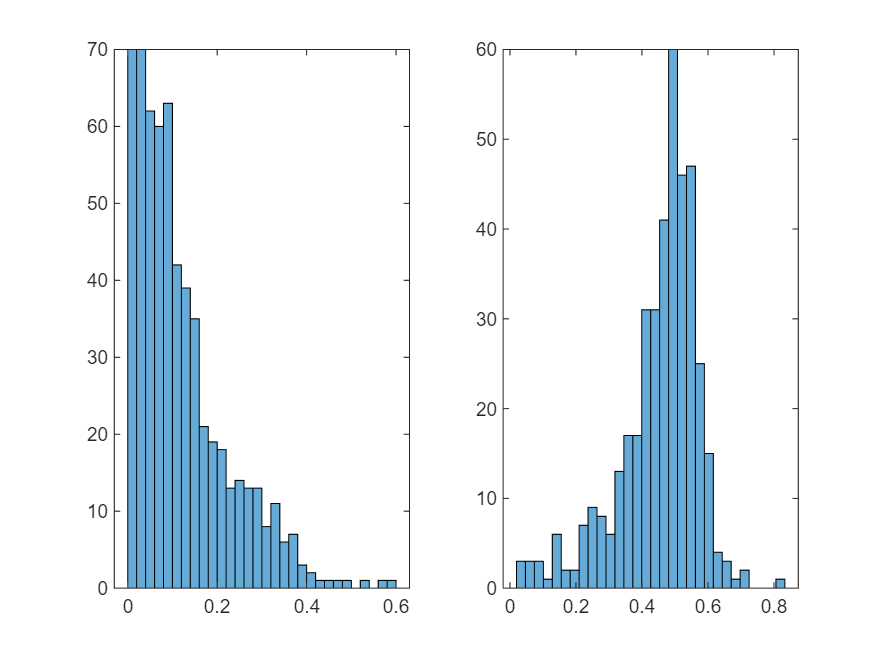

% TODO
uvals = [0,1];
nu = length(uvals);
for i = 1:nu
    I = (u==uvals(i));
    subplot(1,nu,i);
    histogram(rho(I),30);   
    grid on;
end

We will now test a simple thresholding detector:

`   uhat(i) = 1 if rho(i) >= t`

`   uhat(i) = 0 if rho(i) < t`

`for a threshold t.  For the values of threshold in the vector ttest, measure the PFA and PMD.  Plot these as a function of the threhsold.`

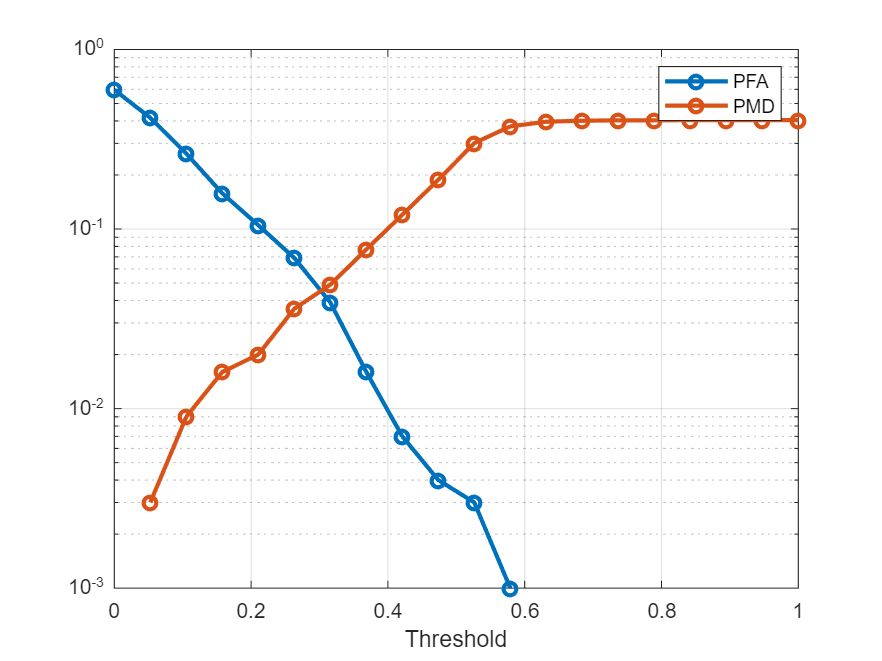

ttest = linspace(0,1,20);  % Thresholds to test

nt = length(ttest);
pfa = zeros(nt,1);
pmd = zeros(nt,1);
for i = 1:nt

    t = ttest(i);

    % TODO: 
    %    xhat = ...
    %    pfa(i) = ...
    %    pmd(i) = ...
    uhat = (rho >= t);
    pfa(i) = mean((uhat==1) & (u == 0));
    pmd(i) = mean((uhat==0) & (u == 1));
end

% TODO:  Plot using semilogy
clf;
semilogy(ttest, [pfa pmd], 'o-', 'LineWidth', 2);
grid on;
legend('PFA', 'PMD');
xlabel('Threshold');
ylim([0.001, 1]);